
testCase = LTSburst_test;

S1 = load(testCase.demofile1);
S2 = load(testCase.demofile2);
S3 = load(testCase.demofile3);

R1 = Record(testCase.demofile1);
R2 = Record(testCase.demofile2);
R3 = Record(testCase.demofile3);


**No input**

bst0 = LTSburst;
disp(bst0)

  LTSburst with properties:

          PreburstSilence_ms: 100
              FirstISImax_ms: 5
               LastISImax_ms: 10
                       Spike: []
                          Fs: []
                       Names: []
                   StartTime: []
                   Groupdata: [0×9 table]
                          Is: []
                   SpikeInfo: {}
                         ISI: {}
                       Onset: {1×0 cell}
                   OnsetInfo: {1×0 cell}
                      Offset: {1×0 cell}
                  OffsetInfo: {1×0 cell}
                     MaxTime: []
                  ISIordinal: {1×0 cell}
              ISIordinalmeta: [0×0 table]
    ISIordinalmeta_perRecord: [0×0 table]
                    LTSstats: [1×0 struct]



**Column vector of 0 or 1**

bst1 = LTSburst(S1.unite.values,1/S1.unite.interval);
bst1.PreburstSilence_ms % 100

ans = 100

bst1

bst1 =   LTSburst with properties:

          PreburstSilence_ms: 100
              FirstISImax_ms: 5
               LastISImax_ms: 10
                       Spike: {[1700000×1 double]}
                          Fs: 17000
                       Names: {''}
                   StartTime: 0
                   Groupdata: [1×9 table]
                          Is: 5.8824e-05
                   SpikeInfo: {[149×1 struct]}
                         ISI: {[150×1 double]}
                       Onset: {[1700000×1 logical]}
                   OnsetInfo: {[37×1 struct]}
                      Offset: {[1700000×1 logical]}
                  OffsetInfo: {[37×1 struct]}
                     MaxTime: 99.9999
                  ISIordinal: {[4×3 table]}
              ISIordinalmeta: [4×3 table]
    ISIordinalmeta_perRecord: [4×3 table]
                    LTSstats: [1×1 struct]


methods(bst1)


Methods for class LTSburst:

LTSburst          plotFistISI       plotISIordinal    
getNperBurstSize  plotISIbefaft     plotTimeView      



all(checkproperties(bst1)) % true

ans =    1


**Cell vector of column vectors of 0 or 1**

bst2 = LTSburst({S1.unite.values},1/S1.unite.interval);
isequal(bst1,bst2) % true

ans =    1


all(checkproperties(bst2)) % true

ans =    1



iscell(bst2.Spike) % true

ans =    1


isa(bst2.Spike{1}, 'double') % true

ans =    1


issparse(bst2.Spike{1}) %sparse double array

ans =    1


testCase.verifyError(@() LTSburst({S1.unite.values,S1.unite.values},1/S1.unite.interval),...
    'K:LTSburst:setFs:length:invalid');

bst3 = LTSburst({S1.unite.values,S2.unite.values,S3.unite.values},...
    [1/S1.unite.interval,1/S2.unite.interval,1/S3.unite.interval]);
disp(bst3);

  LTSburst with properties:

          PreburstSilence_ms: 100
              FirstISImax_ms: 5
               LastISImax_ms: 10
                       Spike: {[1700000×1 double]  [1700000×1 double]  [1700000×1 double]}
                          Fs: [17000 17000 17000]
                       Names: {''  ''  ''}
                   StartTime: [0 0 0]
                   Groupdata: [3×9 table]
                          Is: [5.8824e-05 5.8824e-05 5.8824e-05]
                   SpikeInfo: {[149×1 struct]  [302×1 struct]  [243×1 struct]}
                         ISI: {[150×1 double]  [303×1 double]  [244×1 double]}
                       Onset: {[1700000×1 logical]  [1700000×1 logical]  [1700000×1 logical]}
                   OnsetInfo: {[37×1 struct]  [86×1 struct]  [74×1 struct]}
                      Offset: {[1700000×1 logical]  [1700000×1 logical]  [1700000×1 logical]}
                  OffsetInfo: {[37×1 struct]  [86×1 stru

size(bst3.ISIordinal)% [1,3]

ans =      1     3


size(bst3.ISIordinalmeta_perRecord) %[5,4])

ans =      5     4


all(checkproperties(bst3)) % true

ans =    1


**Record object as input**


bst4 = LTSburst(R1)

bst4 =   LTSburst with properties:

          PreburstSilence_ms: 100
              FirstISImax_ms: 5
               LastISImax_ms: 10
                       Spike: {[1700000×1 double]}
                          Fs: 17000
                       Names: {'kjx006a01@200-300.mat|unite'}
                   StartTime: 0
                   Groupdata: [1×9 table]
                          Is: 5.8824e-05
                   SpikeInfo: {[149×1 struct]}
                         ISI: {[150×1 double]}
                       Onset: {[1700000×1 logical]}
                   OnsetInfo: {[37×1 struct]}
                      Offset: {[1700000×1 logical]}
                  OffsetInfo: {[37×1 struct]}
                     MaxTime: 99.9999
                  ISIordinal: {[4×3 table]}
              ISIordinalmeta: [4×3 table]
    ISIordinalmeta_perRecord: [4×3 table]
                    LTSstats: [1×1 struct]


size(bst4.SpikeInfo{1}) %[149,1]

ans =    149     1


bst4.Names,%'kjx006a01@200-300.mat|unite'});

ans =     'kjx006a01@200-300.mat|unite'


all(checkproperties(bst4))

ans =    1



bst4.Groupdata

ans =       spikeInfo            isi              onset           offset        starttime    maxtime                names                   LTSdef         tooshort  
    ______________    ______________    _____________    _____________    _________    _______    _____________________________    ____________    ____________

    [149×1 struct]    [150×1 double]    [37×1 double]    [37×1 double]    0            100        'kjx006a01@200-300.mat|unite'    [1x1 struct]    [0×2 double]


**cell vector of Record objects as input**


bst5 = LTSburst({R1,R2,R3});
disp(bst5);

  LTSburst with properties:

          PreburstSilence_ms: 100
              FirstISImax_ms: 5
               LastISImax_ms: 10
                       Spike: {[1700000×1 double]  [1700000×1 double]  [1700000×1 double]}
                          Fs: [17000 17000 17000]
                       Names: {1×3 cell}
                   StartTime: [0 0 0]
                   Groupdata: [3×9 table]
                          Is: [5.8824e-05 5.8824e-05 5.8824e-05]
                   SpikeInfo: {[149×1 struct]  [302×1 struct]  [243×1 struct]}
                         ISI: {[150×1 double]  [303×1 double]  [244×1 double]}
                       Onset: {[1700000×1 logical]  [1700000×1 logical]  [1700000×1 logical]}
                   OnsetInfo: {[37×1 struct]  [86×1 struct]  [74×1 struct]}
                      Offset: {[1700000×1 logical]  [1700000×1 logical]  [1700000×1 logical]}
                  OffsetInfo: {[37×1 struct]  [86×1 struct

testCase.verifyTrue(all(checkproperties(bst5)));


testCase.verifyTrue(iscell(bst5.Spike));
testCase.verifyTrue(isa(bst5.Spike{1}, 'double'));
testCase.verifyTrue(issparse(bst5.Spike{1})); %sparse double array

testCase.verifyEqual(bst5.Names,...
    {'kjx006a01@200-300.mat|unite',...
    'kjx010a01@170-270.mat|unite',...
    'kjx015b01@0-100.mat|unite'});



**EventChan as input**

bst6 = LTSburst(R1.unite);
disp(bst6)

  LTSburst with properties:

          PreburstSilence_ms: 100
              FirstISImax_ms: 5
               LastISImax_ms: 10
                       Spike: {[1700000×1 double]}
                          Fs: 17000
                       Names: {'unite'}
                   StartTime: 0
                   Groupdata: [1×9 table]
                          Is: 5.8824e-05
                   SpikeInfo: {[149×1 struct]}
                         ISI: {[150×1 double]}
                       Onset: {[1700000×1 logical]}
                   OnsetInfo: {[37×1 struct]}
                      Offset: {[1700000×1 logical]}
                  OffsetInfo: {[37×1 struct]}
                     MaxTime: 99.9999
                  ISIordinal: {[4×3 table]}
              ISIordinalmeta: [4×3 table]
    ISIordinalmeta_perRecord: [4×3 table]
                    LTSstats: [1×1 struct]



testCase.verifyTrue(all(checkproperties(bst6)));




**cell vector of EventChan as input**

bst7 = LTSburst({R1.unite,R2.unite,R3.unite});
disp(bst7)

  LTSburst with properties:

          PreburstSilence_ms: 100
              FirstISImax_ms: 5
               LastISImax_ms: 10
                       Spike: {[1700000×1 double]  [1700000×1 double]  [1700000×1 double]}
                          Fs: [17000 17000 17000]
                       Names: {'unite'  'unite'  'unite'}
                   StartTime: [0 0 0]
                   Groupdata: [3×9 table]
                          Is: [5.8824e-05 5.8824e-05 5.8824e-05]
                   SpikeInfo: {[149×1 struct]  [302×1 struct]  [243×1 struct]}
                         ISI: {[150×1 double]  [303×1 double]  [244×1 double]}
                       Onset: {[1700000×1 logical]  [1700000×1 logical]  [1700000×1 logical]}
                   OnsetInfo: {[37×1 struct]  [86×1 struct]  [74×1 struct]}
                      Offset: {[1700000×1 logical]  [1700000×1 logical]  [1700000×1 logical]}
                  OffsetInfo: {[37×1 stru

testCase.verifyEqual(bst7.Names,...
    {'unite',...
    'unite',...
    'unite'});
testCase.verifyTrue(all(checkproperties(bst7)));




**No spike input**

bst8 = LTSburst(zeros(10000,1),10000);
testCase.verifyTrue(all(checkproperties(bst8)));

bst9 = LTSburst({S1.unite.values,zeros(10000,1)},...
    [1/S1.unite.interval,1/S1.unite.interval]);
testCase.verifyTrue(all(checkproperties(bst9)));


%% No spike input
empty = EventChan(zeros(10000,1),0,10000);
bst10 = LTSburst(empty);
testCase.verifyTrue(all(checkproperties(bst10)));

%% only one burst included
%TODO

noburst = EventChan(repmat([1;zeros(9999,1)],100,1),0,10000);
bst11 = LTSburst(noburst);

disp(bst11)

  LTSburst with properties:

          PreburstSilence_ms: 100
              FirstISImax_ms: 5
               LastISImax_ms: 10
                       Spike: {[1000000×1 double]}
                          Fs: 10000
                       Names: {''}
                   StartTime: 0
                   Groupdata: [1×9 table]
                          Is: 1.0000e-04
                   SpikeInfo: {[100×1 struct]}
                         ISI: {[101×1 double]}
                       Onset: {[1000000×1 logical]}
                   OnsetInfo: {[0×1 struct]}
                      Offset: {[1000000×1 logical]}
                  OffsetInfo: {[0×1 struct]}
                     MaxTime: 99.9999
                  ISIordinal: {[0×0 table]}
              ISIordinalmeta: [0×0 table]
    ISIordinalmeta_perRecord: [0×0 table]
                    LTSstats: [1×1 struct]



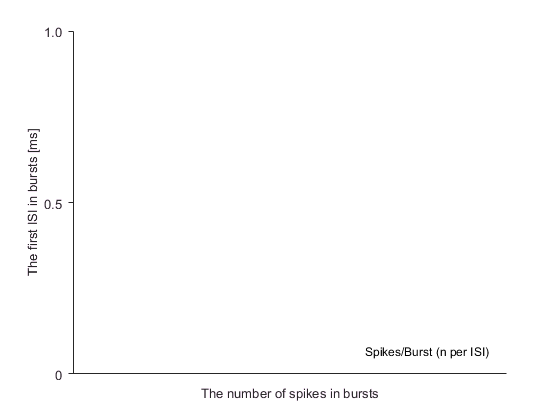

testCase.verifyTrue(all(checkproperties(bst11)));

bst11.plotFistISI;

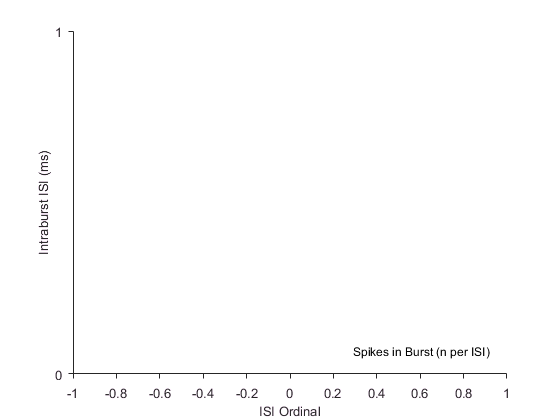


bst11.plotISIordinal;



%% Wrong syntax; Fs is missing
testCase.verifyError(@() LTSburst(S1.unite.values),...
    'K:LTSburst:LTSburst:narginOne:syntax:invalid');

testCase.verifyError(@() LTSburst({S1.unite.values}),...
    'K:LTSburst:LTSburst:narginOne:syntax:invalid');



**Methods**

ans =      fig: [1×1 Figure]
     axh: [1×1 GraphicsPlaceholder]
    line: [1×1 ErrorBar]
    mark: [1×4 Graphics]
     leg: [1×1 Legend]
    axes: [1×1 Axes]


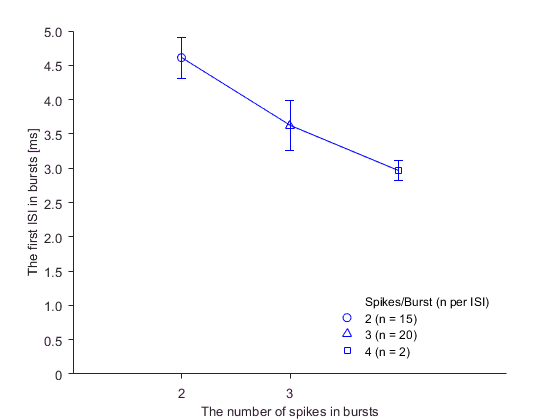

bst1.plotFistISI

ans =      fig: [1×1 Figure]
     axh: [1×1 Axes]
    line: 3.0002


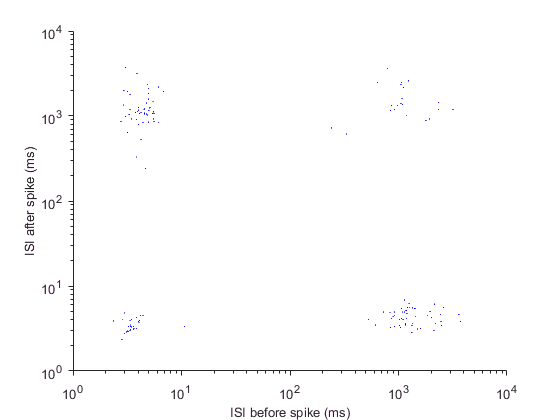


bst1.plotISIbefaft

ans =      fig: [1×1 Figure]
    axes: [1×1 Axes]
    line: [4×1 Graphics]
      e1: [4×1 GraphicsPlaceholder]
     leg: [1×1 Legend]


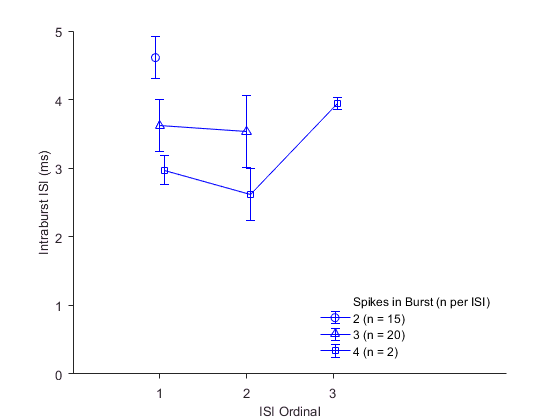


bst1.plotISIordinal

ans =      fig: [1×1 Figure]
    axes: [1×1 Axes]
    line: [4×1 Graphics]
      e1: [4×1 GraphicsPlaceholder]
     leg: [1×1 Legend]


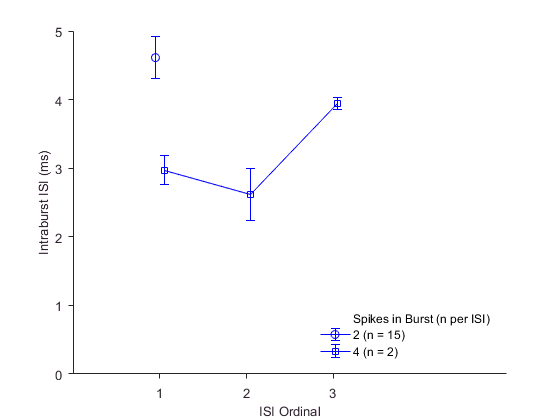


% only subset of data to plot
bst1.plotISIordinal('spikerange',[2,4])

ans =              fig                            axh                   spikeInfo            LTS             onset       onsetNspikes
    ______________________    _______________________________    ____________    _______________    ___________    ____________

    [1x1 matlab.ui.Figure]    [1x1 matlab.graphics.axis.Axes]    [150×1 Line]    [38×1 Graphics]    [37×1 Line]    {5×1 cell}  


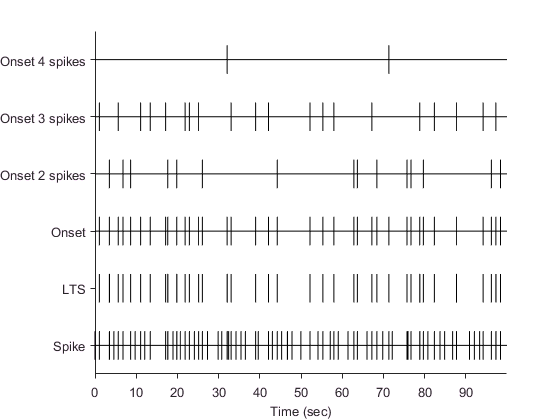


bst1.plotTimeView